clear all; close all; clc

Class Excercise 2

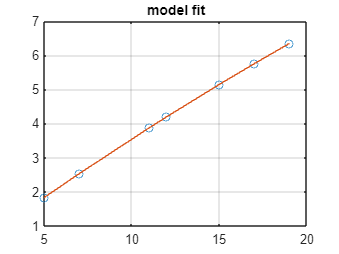

% y = x/(e^(θ1+θ2x) + 1)
% 1/y = (e^(θ1+θ2x) + 1)/x
% 1/y = (e^(θ1+θ2x)/x + 1/x
% 1/y - 1/x = (e^(θ1+θ2x)/x
% log(1/y -1/x) = log((e^(θ1+θ2x)/x)
% log(1/y - 1/x) + log (x) = log((e^(θ1+θ2x))
% log(1/y - 1/x) + log (x) = θ1 + θ2x

% ............ log (1/y - 1/x) + log (x) = θ1 + θ2x
X = [5 7 11 12 15 17 19]';
Y = [1.83 2.53 3.87 4.20 5.14 5.75 6.35]';
n = length(X); % extract the length of data
XX = [ones(n,1) X]; % Define the coefficient matrix
YY = log(1./Y - 1./X) + log(X); % log transformation
params = XX\YY; % estimate the parameters
theta1 = params(1); % recover the original parameter values
theta2 = params(2);
theta = [theta1, theta2];
Yfit = X./(exp(theta1+theta2*X)+1); % Get the fitted values
figure;
plot(X,Y,'o',X,Yfit) % plot data and fitted values
title('model fit');
grid on

Class Excercise 1 : First Load given data file Data_class.mat

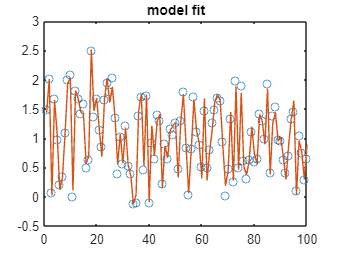

% Fitting a linear model to data
% The data:
X = [x1 x2];
Y = y;
n = length(Y); % number of data points
% constructing the design matrix
X2 = [X(:,1) X(:,2) X(:,2).^2];
b = X2\Y; % LSQ fit
yfit = X2*b; % model response
% visualizing the fit
figure;
plot(1:n,Y,'o',1:n,yfit); title('model fit');